## Simulazione miscelazione in tank(2.3)

#### Variabili

rho = 900;                          %Densità [Kg/m^3]

w1 = 500;                           %Portata stream 1 [Kg/min]
w2 = 200;                           %Portata stream 2 [Kg/min]
w = 650;                            %Porata in uscita [Kg/min]

x1 = 0.4;                           %Composizione dello stream 1, frazione ponderale [adim]
x2 = 0.75;                          %Composizione dello stream 2, frazione ponderale [adim]

### Equazioni risolutive

Il sistema è composto da una cisterna con due stream in ingresso e una di uscita, questo viene definito tramite le seguenti equazioni, rispettivamente il bilancio totale di materia e il bilancio di materia per la specie A.


$$\frac{dV}{dt}=\frac{1}{\rho}(w_1 + w_2 - w)$$



$$\frac{dx_A}{dt}=\frac{1}{\rho V}(w_1(x_1 -x)+w_2(x_2 -x))$$



$$\frac{dx_A}{dt}=\frac{1}{\rho V}(w_1((1-x_1) -x)+w_2((1-x_2) -x))$$


#### Soluzione del sistema di equazioni

Per risolvere il sistema di equazioni in esame si utilizza la libreria di MATLAB odes.

tspan = linspace(0.1,10,100);         %Vettore tempi per il calcolo
x0 = 0.3;                             %Concentrazione iniziale, frazione ponderale [adim]
Vol0 = 2;                           %Volume iniziale pieno nel serbatoio [metri cubi]
y0 = [x0 Vol0];                     %Vettore delle condizioni iniziali
options = odeset('RelTol',1e-3);
[t,sol] = ode15s(@MBs,tspan,y0,options,w1,w2,w,x1,x2,rho);

### Grafici e risultati

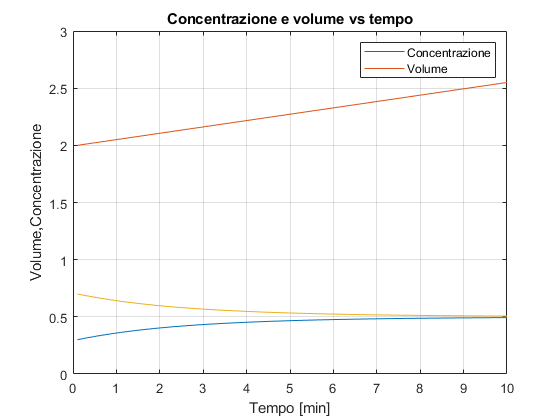

%Calcolo la concentrazione di B
concb = 1-sol(:,1);
figure(1)
plot(t,sol(:,1)),hold on
plot(t,sol(:,2))
plot(t,concb)
grid on
xlabel('Tempo [min]')
ylabel('Volume,Concentrazione')
title('Concentrazione e volume vs tempo')
legend('Concentrazione','Volume')

### Consideriamo il caso in cui OUTPUT = INPUT e Volume Costante

In questa condizione al sistema possono essere aggiunte le seguenti condizioni di stazionarieità

$\frac{dV}{dt}=0

$ e $w=w_1+w_2$

Si ottiene cosi una nuova equazione di bilancio 


$$\frac{dx}{dt}=\frac{1}{\rho V}(w_1(x_1-x)+w_1(x_2-x))=0$$


Da cui posso ottenre


$$\overline{x}=\frac{w_1x_1 + w_2x_2}{w_1+w_2}$$


Il valore medio della concentrazione di x all'interno del serbatoio può essere stimato come segue

meanx=(w1*x1 + w2*x2)/(w1+w2);

Per controllare che il risultato sia correto si procede al calcolo della media del vettore risultante nel caso precedente 

meancase1=mean(sol(:,1));

Calcolo la differenza

Diff=meanx-meancase1;

Possiamo notare come la differenza tra i due calcoli diminuisce all'aumentare del tempo, infatti possiamo notare che la variazione di concentrazione sul lungo periodo tende allo stato stazionario ipotizzato per le condizioni del secondo caso.

### Funzione per soluzione del problema nella cisterna

function [sol] = MBs(t,y0,w1,w2,w,x1,x2,rho)
x = y0(1);
V = y0(2);
dVdt = (w1 + w2 - w)/rho;                   %Bilancio totale di materia
dxdt = (w1*(x1-x)+w2*(x2-x))/(rho*V);
sol = [dxdt dVdt]';
end